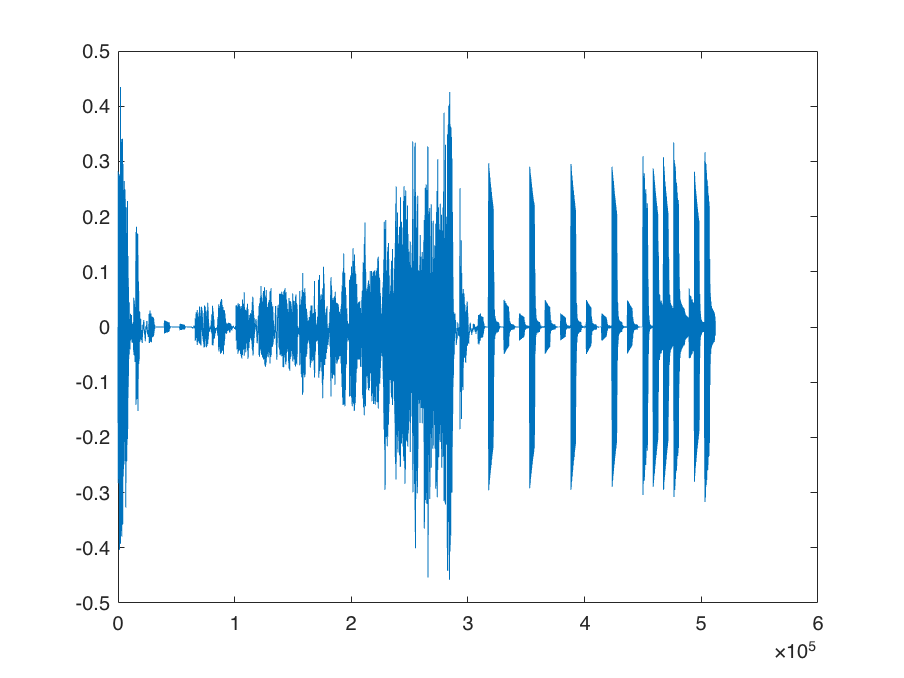

clear
audio = "hey01.wav";
[Y, fs] = audioread(audio{1});
plot(Y)

clear plot
hold off

raw_audio = Y(:,:);

Ymax = max(Y)

Ymax = 0.4348

Ymin = min(Y)

Ymin = -0.4578

delta = .0695

delta = 0.0695

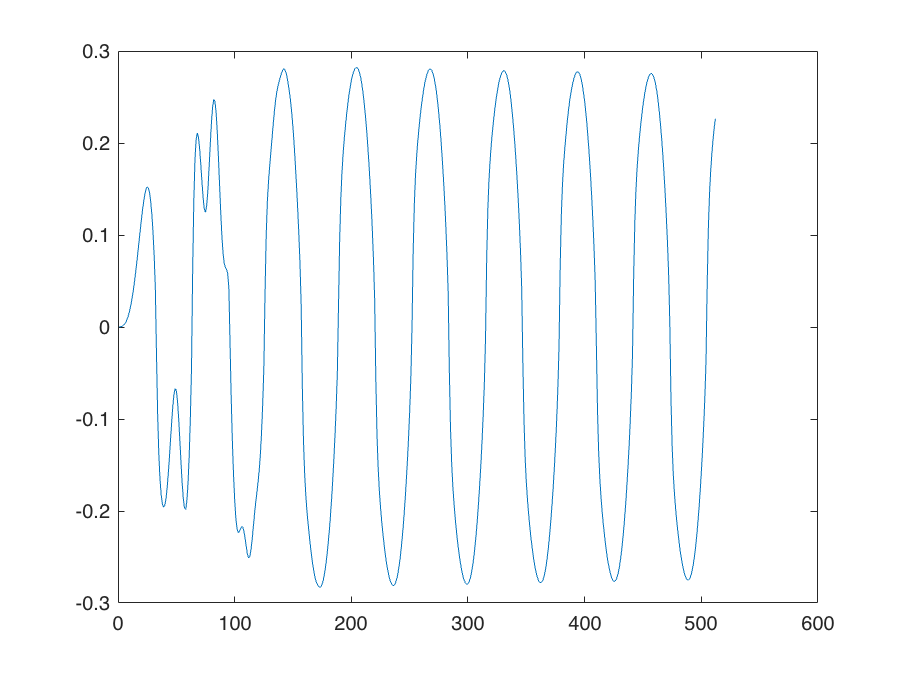

blocksize = 512;

% Divide in blocks of set blocksize
raw_audio_blocks = reshape(raw_audio, blocksize,[] );

oneBlock = raw_audio_blocks(:,1);
plot(oneBlock)

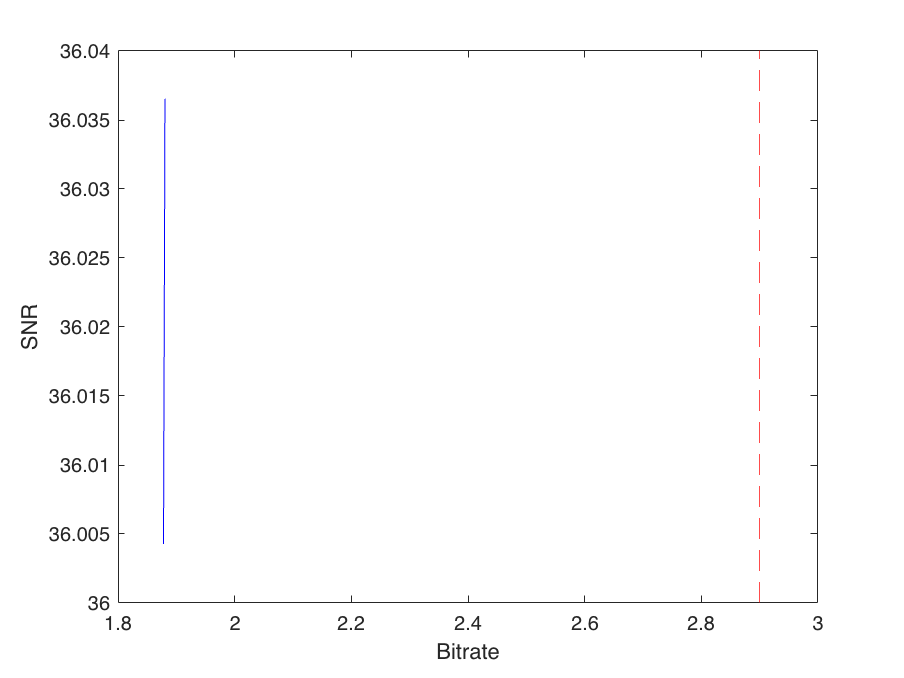


for k = 1:4

    delta = 0.069+k*10^-4;

    columnSums = mdct(raw_audio, blocksize);
    y_transformed = dct(raw_audio);
    y_quantize = quantize(columnSums, delta);
    c = uniqueIndex(y_quantize);
    num = accumarray(c,1);
    p = num/sum(num);
    %plot(y_transformed);
    rate = huffman(p);
    H = entropyOfDistribution(p);
    yhat = imdct(y_quantize*delta);
    %plot(raw_audio);
    diff = raw_audio - (yhat);
    % Distorsion
    D = mean(mean(diff.^2));
    %SNR
    SNR = 10*log10(var(raw_audio)/D);
    %fprintf('Blocksize:\n %.0f',blocksize)
    %fprintf('Rate: %.4f dB',rate)
    %fprintf('Entropy: %.4f dB',H)
    %fprintf('SNR: %.2f dB',SNR)
    SNR_arr(k) = SNR;
    rate_arr(k) = rate;
end

plot(rate_arr, SNR_arr, 'b')
hold on
xline(2.9, '--r')
xlabel('Bitrate');
ylabel('SNR');
hold off

function out = quantize(x, delta)

out = round(x/delta);

end
function index = uniqueIndex(x)

[~,~,index] = unique(x);

end